clearvars;
%measurement settings
format shortG
xmin = -5;
xmax = 5;
ymin = -5;
ymax = 5;
zmin = 0;
zmax = 5;
xint = 0.5;
yint = 0.5;
zint = 0.5;
xtotal = ((xmax-xmin)/xint + 1);
ytotal = ((ymax-ymin)/yint + 1);
ztotal = ((zmax-zmin)/zint + 1);
%datasize = xtotal*ytotal*ztotal;
%magnet parameters
3/16

ans =        0.1875


1/8

ans =         0.125


diameter = 3/16*25.4 %mm

diameter =        4.7625


height = 1/8*25.4 %mm

height =         3.175


Br_max = 12100*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 35; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 35; %mm

%this is for averaging the measurements at a specific location
% location = [];
% z = zmin;
% dataavg = [];
% 
% for k = 1:ztotal
%     zstr = sprintf('%.1f', z);
%     y = ymin;
% 
%     for j = 1:ytotal
%         ystr = sprintf('%.1f', y);
%         x = xmin;
% 
%         for i = 1:xtotal
% 
%             xstr = sprintf('%.1f', x);
%             filename = append('C:\Users\Brandon Nguyen\Documents\Github\magnetic-sensor-data\PIM06152023_magnet4\',xstr,'_',ystr,'_',zstr,'.data');
%             test = importdata(filename);
%             
%             bx1 = test.data(1:99,6);
%             by1 = test.data(1:99,7);
%             bz1 = test.data(1:99,8);
% 
%             bx2 = test.data(100:199,6);
%             by2 = test.data(100:199,7);
%             bz2 = test.data(100:199,8);
% 
%             bx3 = test.data(200:299,6);
%             by3 = test.data(200:299,7);
%             bz3 = test.data(200:299,8);
%             
%             bx4 = test.data(300:399,6);
%             by4 = test.data(300:399,7);
%             bz4 = test.data(300:399,8);
%             dataavg = [dataavg 
%                 [mean(bx1) mean(by1) mean(bz1) mean(bx2) mean(by2) mean(bz2) mean(bx3) mean(by3) mean(bz3) mean(bx4) mean(by4) mean(bz4)]];
%             location = [location
%                 [x y z]];
%            
%             x = x + xint;
%         end
%         y = y + yint;
%     end
%     z = z + zint;
% end

% writematrix(dataavg, 'C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06152023_magnet4averages.txt');
% writematrix(location, 'C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06152023_magnet4locations.txt')

dataavg = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06152023_magnet4averages.txt');
location = importdata('C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM06152023_magnet4locations.txt');

sen1 = dataavg(:,1:3) %bottom left sensor

sen1 =     -0.023227    -0.055588    -0.062975
    -0.023232    -0.055588     -0.06299
    -0.023221    -0.055594    -0.062957
    -0.023209    -0.055599    -0.063007
     -0.02324    -0.055593    -0.062986
    -0.023214    -0.055585    -0.062948
    -0.023186    -0.055617    -0.062999
    -0.023558    -0.055771    -0.062992
    -0.023076    -0.055758    -0.063197
    -0.021846    -0.065357    -0.071591


sen2 = dataavg(:,4:6) %bottom right sensor

sen2 =      0.013903   -0.0054576   -0.0039599
     0.013898   -0.0055074   -0.0039998
     0.013921    -0.005494   -0.0039969
     0.013904   -0.0053926   -0.0040223
      0.01392   -0.0054882   -0.0040105
     0.013942   -0.0052962   -0.0039726
     0.013968   -0.0053941   -0.0039772
     0.012947   -0.0052587   -0.0037667
     0.013994   -0.0055239   -0.0040736
     0.017453   -0.0060063   -0.0049155


sen3 = dataavg(:,7:9) %top left sensor (the magnet is centered above this sensor)

sen3 =   -0.00071631  -0.00019715     -0.19859
  -0.00070198  -0.00021288     -0.19859
  -0.00069103  -0.00020761     -0.19859
  -0.00066495  -0.00021006     -0.19859
  -0.00064408  -0.00022567     -0.19859
  -0.00058985   -0.0002283     -0.19859
  -0.00055974  -0.00021312     -0.19859
    -0.000728  -0.00021527     -0.19859
  -0.00038107  -0.00020455     -0.19859
     0.011954     0.045036      -0.1986


sen4 = dataavg(:,10:12) %top right sensor

sen4 =       0.04233    0.0096219    -0.044701
     0.042321    0.0096579    -0.044683
     0.042317    0.0096829    -0.044659
     0.042335    0.0096604     -0.04466
     0.042317    0.0096937    -0.044583
     0.042328    0.0097177    -0.044575
     0.042341    0.0096733     -0.04459
     0.041863      0.00993    -0.044479
     0.042394    0.0095214    -0.044757
     0.039166     0.016633    -0.042119


X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 1], 4851, 1);
expectB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

expectB =      0.049256     0.049256      0.22517
     0.044746     0.049718      0.22773
     0.040109     0.050137      0.23005
     0.035357      0.05051      0.23213
     0.030502     0.050836      0.23394
     0.025557     0.051115      0.23549
     0.020538     0.051345      0.23677
     0.015457     0.051524      0.23777
     0.010331     0.051653      0.23849
     0.005173      0.05173      0.23892


testB = 2*sen3

testB =    -0.0014326   -0.0003943     -0.39718
    -0.001404  -0.00042576     -0.39718
   -0.0013821  -0.00041523     -0.39718
   -0.0013299  -0.00042012     -0.39718
   -0.0012882  -0.00045134     -0.39718
   -0.0011797   -0.0004566     -0.39719
   -0.0011195  -0.00042625     -0.39719
    -0.001456  -0.00043053     -0.39718
  -0.00076215  -0.00040911     -0.39718
     0.023907     0.090073      -0.3972


%fitting for the angle, the sensor is at (0,0,0)
ind = 10;
d_data = sen3;
loc = location + [0 0 35];
datasize = length(sen3);
dcostfun = @(v)anglecost(v, loc, d_data, B_t, datasize);
nonlcon = @con;
        
x0 = [0,0,0];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1,-1];
ub = [1,1,1];
[angle, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


angle =      -0.22465     -0.11427     -0.96772


fval =        9.7471


fval/datasize

ans =     0.0020093


sqrt(sum(angle.^2))

ans =             1


%fitting for the location using the angle from above, the sensor is at (0,0,0)
fixapreds = [];
fixafvalues = [];
for t = 1:length(sen3)
    B_data = sen3(t,:);
    costfun = @(v)loccost(v, angle, B_data, B_t);
    nonlcon = @con;

    x0 = [-5,-5,35];
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    lb = [-20, -20, 30];
    ub = [20, 20, 60];
    [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
    fixapreds = [fixapreds; locs];
    fixafvalues = [fixafvalues; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

%fitting for the angle with 2x measured B, the sensor is at (0,0,0)
ind = 10;
d_data = testB;
loc = location + [0 0 35];
datasize = length(sen3);
dcostfun = @(v)anglecost(v, loc, d_data, B_t, datasize);
nonlcon = @con;
        
x0 = [0,0,0];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1,-1];
ub = [1,1,1];
[angle, fval] = fmincon(dcostfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


angle =     -0.035187    -0.017899     -0.99922


fval =        67.983


fval/datasize

ans =      0.014014


sqrt(sum(angle.^2))

ans =             1


X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([angle], 4851, 1);
faB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

faB =     -0.045382     -0.04745     -0.22761
    -0.040796    -0.047878     -0.23002
    -0.036088    -0.048263     -0.23218
    -0.031271    -0.048604      -0.2341
    -0.026358    -0.048898     -0.23574
    -0.021363    -0.049145     -0.23712
      -0.0163    -0.049344     -0.23823
    -0.011184    -0.049494     -0.23905
   -0.0060285    -0.049594     -0.23959
  -0.00085011    -0.049643     -0.23984


expectB

expectB =      0.049256     0.049256      0.22517
     0.044746     0.049718      0.22773
     0.040109     0.050137      0.23005
     0.035357      0.05051      0.23213
     0.030502     0.050836      0.23394
     0.025557     0.051115      0.23549
     0.020538     0.051345      0.23677
     0.015457     0.051524      0.23777
     0.010331     0.051653      0.23849
     0.005173      0.05173      0.23892


fabdiff = expectB - faB

fabdiff =      0.094639     0.096707      0.45278
     0.085542     0.097597      0.45775
     0.076197       0.0984      0.46224
     0.066628     0.099113      0.46622
      0.05686     0.099734      0.46969
     0.046921      0.10026      0.47262
     0.036838      0.10069        0.475
     0.026641      0.10102      0.47682
     0.016359      0.10125      0.47808
    0.0060232      0.10137      0.47876


max(fabdiff)

ans =       0.18202      0.18509       0.8065


%fitting for the location using the angle from above with 2x measured B, the sensor is at (0,0,0)
fixapreds = [];
fixafvalues = [];
for t = 1:length(sen3)
    B_data = sen3(t,:);
    costfun = @(v)loccost(v, angle, B_data, B_t);
    nonlcon = @con;

    x0 = [-5,-5,35];
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    lb = [-20, -20, 30];
    ub = [20, 20, 60];
    [locs, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub);
    fixapreds = [fixapreds; locs];
    fixafvalues = [fixafvalues; fval];
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

X1 = [0 0 0] - location + [0 0 35];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([angle], 4851, 1);
expectB = B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)

expectB =     -0.045382     -0.04745     -0.22761
    -0.040796    -0.047878     -0.23002
    -0.036088    -0.048263     -0.23218
    -0.031271    -0.048604      -0.2341
    -0.026358    -0.048898     -0.23574
    -0.021363    -0.049145     -0.23712
      -0.0163    -0.049344     -0.23823
    -0.011184    -0.049494     -0.23905
   -0.0060285    -0.049594     -0.23959
  -0.00085011    -0.049643     -0.23984


fixapreds

fixapreds =       0.53818       0.2508       37.987
      0.53642      0.25273       37.987
      0.53504      0.25205       37.987
      0.53178      0.25229       37.987
      0.52921      0.25419       37.987
      0.52243      0.25438       37.987
      0.51862      0.25241       37.987
      0.53969       0.2531       37.987
      0.49625       0.2509       37.987
      -1.0247      -5.3171       37.124


fixafvalues

fixafvalues =    1.4631e-10
   1.6707e-10
   1.7085e-10
   1.9146e-10
   2.2017e-10
   2.6779e-10
   2.8021e-10
   1.5136e-10
   4.5325e-10
   2.1269e-10


fixadiff = fixapreds - loc

fixadiff =        5.5382       5.2508       2.9865
       5.0364       5.2527       2.9866
        4.535        5.252       2.9868
       4.0318       5.2523       2.9866
       3.5292       5.2542       2.9867
       3.0224       5.2544       2.9866
       2.5186       5.2524       2.9867
       2.0397       5.2531       2.9867
       1.4962       5.2509        2.987
     -0.52468     -0.31707        2.124


max(fixadiff)

ans =         5.541       12.142       9.7586


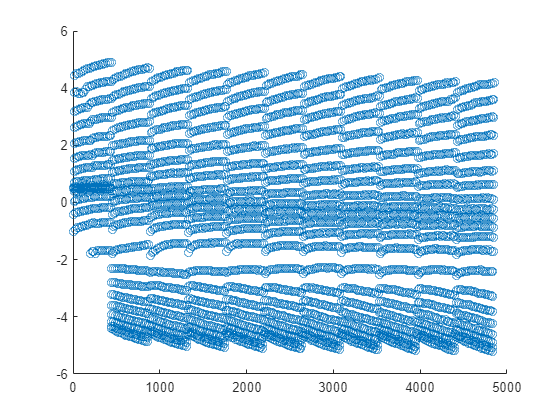

%predicted location using fixed angle
scatter(1:4851,fixapreds(:,1)) %x values

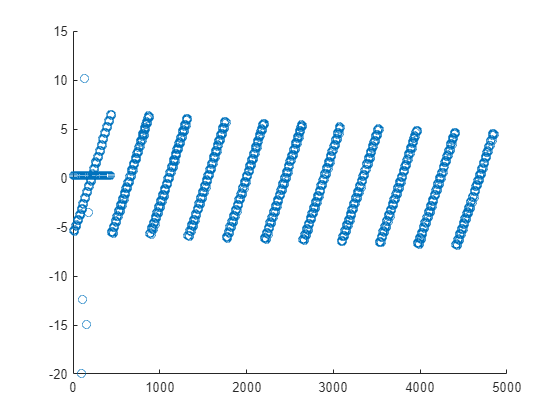

scatter(1:4851,fixapreds(:,2)) %y values

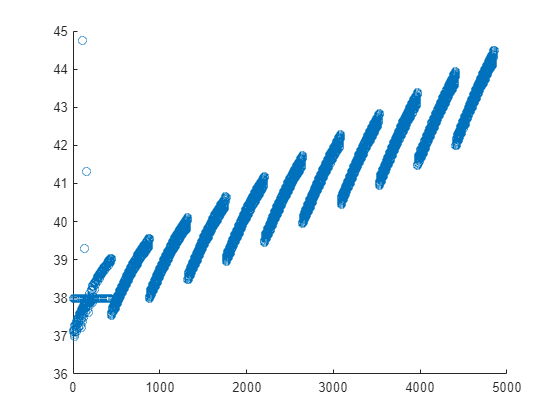

scatter(1:4851,fixapreds(:,3)) %z values

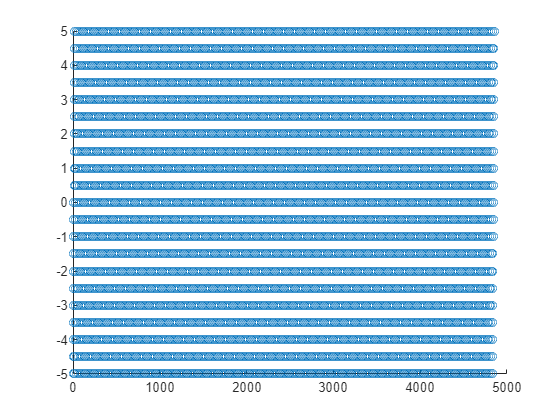

% scatter(1:4851,fixadiff(:,1))
% scatter(1:4851,fixadiff(:,2))
% scatter(1:4851,fixadiff(:,3))

%actual location of measurement
scatter(1:4851,loc(:,1))

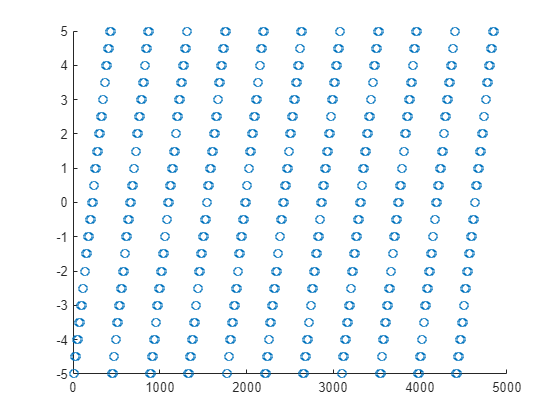

scatter(1:4851,loc(:,2))

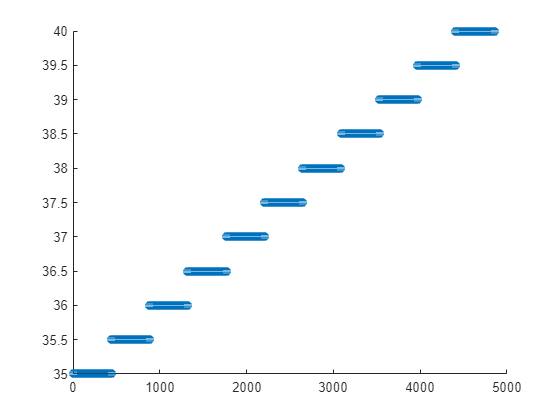

scatter(1:4851,loc(:,3))

testx = sen3 + [0 0 0]

testx =   -0.00071631  -0.00019715     -0.19859
  -0.00070198  -0.00021288     -0.19859
  -0.00069103  -0.00020761     -0.19859
  -0.00066495  -0.00021006     -0.19859
  -0.00064408  -0.00022567     -0.19859
  -0.00058985   -0.0002283     -0.19859
  -0.00055974  -0.00021312     -0.19859
    -0.000728  -0.00021527     -0.19859
  -0.00038107  -0.00020455     -0.19859
     0.011954     0.045036      -0.1986


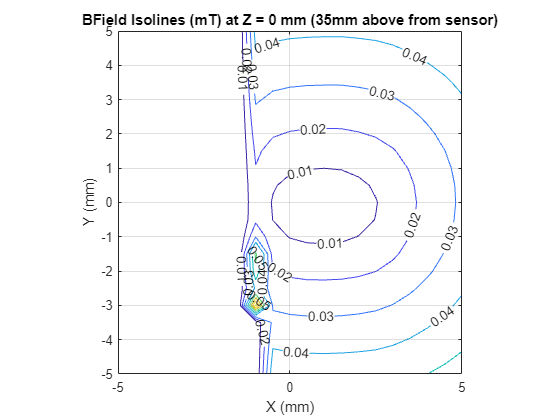

locavg = [location testx];
format longG
zzero = find(abs(locavg(:,3)-0) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;

axis image
grid on;
title('BField Isolines (mT) at Z = 0 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

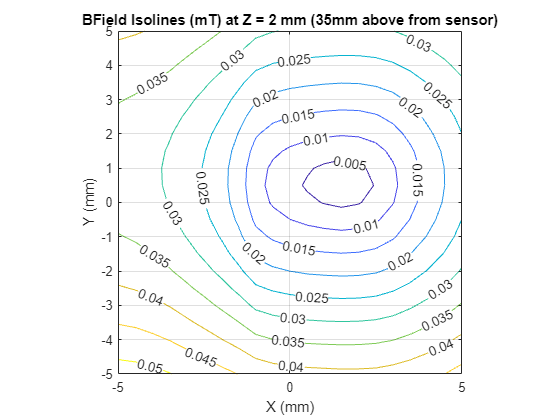

zzero = find(abs(locavg(:,3)-2) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
axis image
grid on;
title('BField Isolines (mT) at Z = 2 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

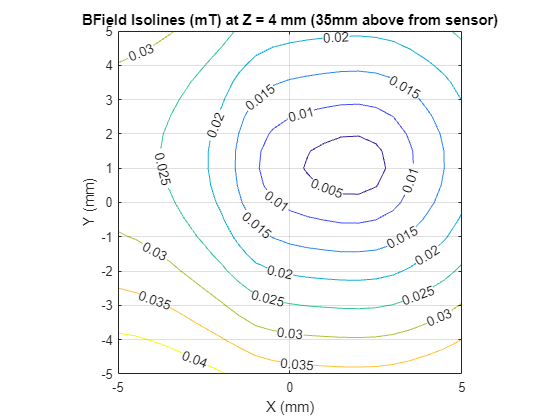

zzero = find(abs(locavg(:,3)-4) < 0.1);

zzeromat = locavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(441) sqrt(441)]);
zerox = reshape(zzeromat(:,1), [sqrt(441) sqrt(441)]);
zeroy = reshape(zzeromat(:,2), [sqrt(441) sqrt(441)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
axis image
grid on;
title('BField Isolines (mT) at Z = 4 mm (35mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

06/06/2023

Meeting Notes

Rotate all sensors and repeat measurement to see if the same stretching happens.

Satwik has circuit board design done and ordered

Sensors are 25mm apart

Maybe try multi sensor with fixed angle (180,000 points) 

Put together Pi and Screen

Stronger magnet, Satwik says he found N55 strength, [https://buymagnets.com/product/neodymium-disc-magnets-n55/](https://buymagnets.com/product/neodymium-disc-magnets-n55/)

Figure out what magnet to buy for next week, look for even stronger magnets

06/13/2023

Test the other N35 magnets for this stretching

check if printer motion is consistent in all three axes

try switching the order of the x and y axes in calibration

measure background

will need to solder sensors onto pcb, look for solder paste and a heat gun.

look for local reseller of bunting magnet, or a way to reduce shipping.

% %fitting for the angle and location, the sensor is at (0,0,0)
% preds = [];
% fvalues = [];
% for t = 1:length(sen3)
%     B_data = sen3(t,:);
%     costfun = @(v)bothcost(v, B_data, B_t);
%     nonlcon = @con;
% 
%     x0 = [0,0,0, -5,-5,35];
%     A = [];
%     b = [];
%     Aeq = [];
%     beq = [];
%     lb = [-1,-1,-1,-7, -7, 0];
%     ub = [1,1,1, 7, 7, 50];
%     [mins, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub, nonlcon);
%     preds = [preds; mins];
%     fvalues = [fvalues; fval];
% end

% anglepred = preds(:,1:3)
% locpred = preds(:,4:6)
% fvalues
% loc
% diff = locpred-loc
% max(diff)
% max(anglepred(:,1))
% max(anglepred(:,2))
% min(anglepred(:,3))

% %predicted location from fitting angle and location
% scatter(1:4851,locpred(:,1)) %x values
% scatter(1:4851,locpred(:,2)) %y values
% scatter(1:4851,locpred(:,3)) %z values
% % scatter(1:4851,fixadiff(:,1))
% % scatter(1:4851,fixadiff(:,2))
% % scatter(1:4851,fixadiff(:,3))
% 
% %actual location of measurement
% scatter(1:4851,loc(:,1))
% scatter(1:4851,loc(:,2))
% scatter(1:4851,loc(:,3))

% scatter(1:4851, sen3(:,1))
% hold on;
% grid on;
% xlim([0 100])
% hold off;
% scatter(1:4851, sen3(:,2))
% hold on;
% grid on;
% xlim([0 100])
% hold off;
% scatter(1:4851, sen3(:,3))
% hold on;
% grid on;
% xlim([0 100])
% hold off;

function a = anglecost(v, loc, B_data, B_t, datasize)
X1 = [0 0 0] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], datasize, 1);
a = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function b = loccost(x, angle, B_data, B_t)
X1 = [-x(1) -x(2) -x(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem(angle, 1, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function b = bothcost(v, B_data, B_t)
H_0 = repelem([v(1) v(2) v(3)], 1, 1);
X1 = [-v(4) -v(5) -v(6)];
R1 = sqrt(sum(X1.^2, 2));
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end